%Pesos [N]
wb=0.105948;
wcp= 0.014145;
wm=0.030411; 

%Distancias [m]
d1=130.75e-3;
d2=50.75e-3;
e=41.91e-3;

%Momento de inercia [kg-m^2]
I=15e-5; 

%Coeficiente término \theta
Coeficiente = wcp*d2-wm*d1-wb*e

Coeficiente = -0.0077


%Ángulo de linealización
thetap = 90; 

%Constante del motor
km=0.00118;

%Constante de Fricción
beta = 1.667;
miu=beta*2*I;

%TransferFunction
s=tf('s');
c = (((wcp*d2-wm*d1-wb*e)/I)*(-cosd(thetap)));
G=((km*d1)/I)/((s^2)+(miu/I)*s+(((wcp*d2-wm*d1-wb*e)/I)*(-cosd(thetap))))

G =
 
      1.029
  -------------
  s^2 + 3.334 s
 
Continuous-time transfer function.



pole(G)

ans =          0
   -3.3340


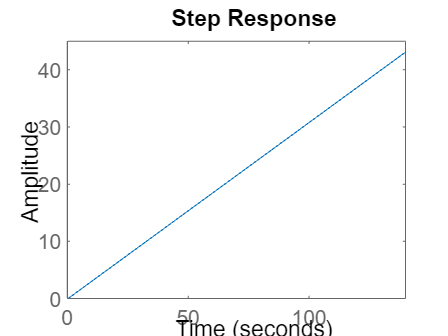


step(G)

Gnum = cell2mat(G.Numerator)

Gnum =          0         0    1.0286


Gden = cell2mat(G.Denominator)

Gden =     1.0000    3.3340         0



[Gm Pm Wcg Wcp] = margin(G)

Gm = Inf

Pm = 84.7360

Wcg = Inf

Wcp = 0.3072

Gm = 20*log10(Gm)

Gm = Inf